Elapsed time is 1.886587 seconds.
Elapsed time is 2.207506 seconds.


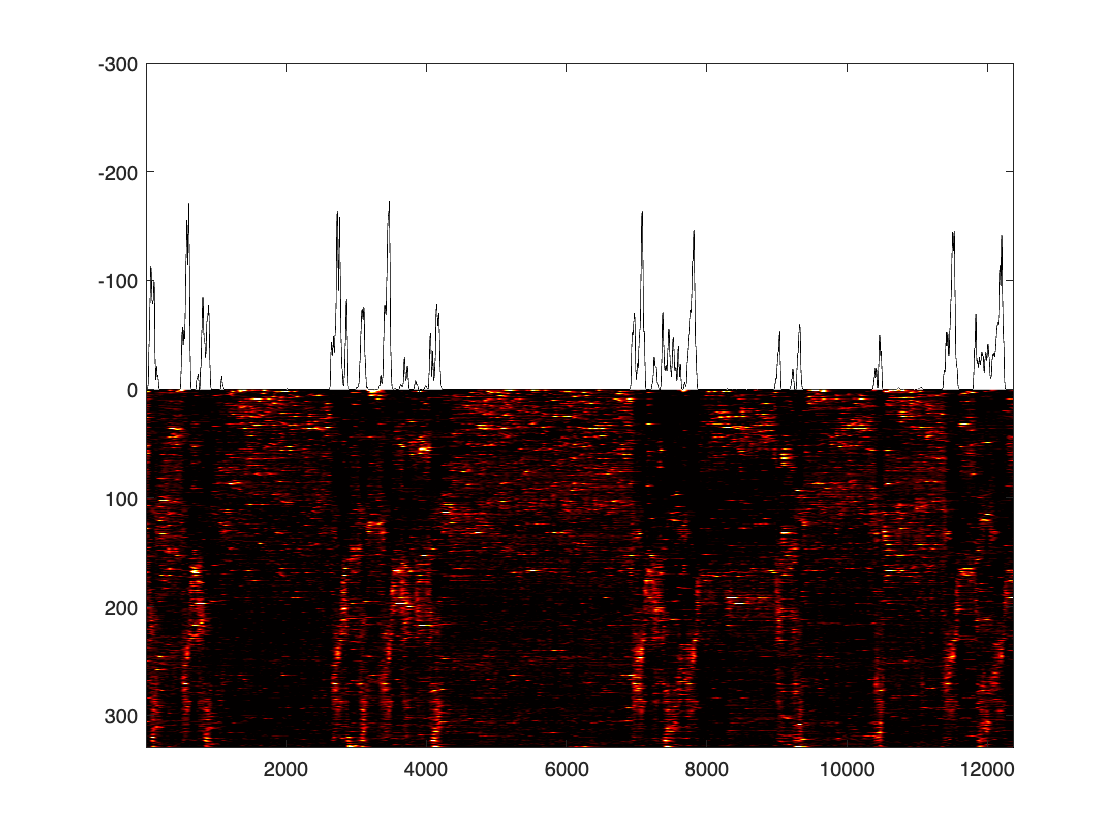

%%load file
%load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_21_01_51_55P2M_444118_220914_plane0_2023_05_04.08-47-27assemblysce6last/brainbow.mat')
%load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_22_13_11_20P2M_444175_221125_plane0_2023_10_25.17-43-15assemblysce6last/brainbow.mat')
% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/23_12_24_16_42_06P2M_411582_230320_plane1_2023_04_05.17-57-09assemblysce6last/brainbow.mat')%,'Tr1b','WinActive','WinRest','Race')
% num_recording = [1     2     7    15    18    22    23    24    29    34];%list_444118
% num_recording = [3	25	30	35	36]; %list_444119
% num_recording = [ 4	8	9	14	16	26	27	31	32]; %444152
%num_recording = [5	10	12	13	17	19	37	38	39	40] ; %444175
% num_recording = [6 33];  %411582
% num_recording = [11 20] ; %443669
% num_recording = [21 28];  %444112
% num_recording =[6 11 21 2 18 1 23 34 3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
clear
close all
% num_recording =[6 11 21 2 18 1 23  3 25 8 26 4 9 5 10 12 17 13]; %all but only one time
% load('/Users/platel/Desktop/exp/brainbow hippocampus/best/best.mat')
load('/Users/platel/Desktop/exp/brainbow hippocampus/bestcue/bestcue.mat')
newlist=matfile;
PathSave= '/Users/platel/Desktop/exp/brainbow hippocampus/analysis/cue-correlation/';
for file_num=14:numel(newlist)
filename=cell2mat(newlist(file_num));
load (filename,'assembly','F','speed','iscell','NCell','NClOK','Nz','colorcell','CellClraw','color_assembly')
[path,name,ext] = fileparts(filename);
[path,name,ext] = fileparts(path);
% load (filename)
%%use of rastermap on winactive part of recording
 
ops.nC = 20;%, number of clusters to use 
ops.iPC = 1:40;%, number of PCs to use 
ops.isort = [];%, initial sorting, otherwise will be the top PC sort
ops.useGPU = 0;%, whether to use the GPU
ops.upsamp = 100;%, upsampling factor for the embedding position
ops.sigUp = 1;%, % standard deviation for upsampling

%preprocessing signal
%DF=Tr1b./std(Tr1b,0,2);

DF=double(F(iscell(:,1)>0,:));
ws = warning('off','all');
for i=1:NCell
    p0=polyfit(1:Nz,DF(i,:),3);
    DF(i,:)=DF(i,:)./polyval(p0,1:Nz);
end
warning(ws)%% preprocessing
DF = sgolayfilt(DF',3,5)';%was at 5
% DF=normalize(DF,2,"medianiqr");
% DF=normalize(DF,2,"zscore");
DF=normalize(DF,2,"center","median","scale","mad");
% DF=normalize(DF,2,"center","mean","scale","std");
Fcenter=normalize(DF,2,"center","mean");
Tr1b=DF;

% [isort1, isort2, Sm] = mapTmap(DF(:,WinActive),ops);
[isort1, isort2, Sm] = mapTmap(DF,ops);
% DF=Tr1b(isort1,:);
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,:))
% imagesc(Ftemp(isort1,WinActive))
caxis ([0 10])
colormap ("hot")
hold on
plot (-speed*10,'Color','k')
% plot (-binary_signal*20)
% % plot (-cumulativeDistance/10)
% % hold off
% caxis ([0 10])
% text(isort2(1:100),repmat(-10,100,1),'*')
ylim([-300 NCell]) 
hold off
    namegraph=strcat(['rastermap_run' , name, '.png']);
    exportgraphics(gcf,[PathSave namegraph],'Resolution',300)

%representation with cumulative distance
sampling_rate=10;
deltaTime = 1/sampling_rate; % Time interval between measurements, adjust as necessary

% Convert speed to distance for each interval
distanceMatrix = speed * deltaTime; % If deltaTime is 1, this line can be omitted

% Calculate cumulative distance
cumulativeDistance = cumsum(distanceMatrix, 1); % Assuming time is along the second dimension (columns)
epsilon = 1e-6; % Small value to adjust duplicates
for i = 2:length(cumulativeDistance)
    while ismember(cumulativeDistance(i), cumulativeDistance(1:i-1))
        cumulativeDistance(i) = cumulativeDistance(i) + epsilon;
    end
end
% Desired distances for interpolation
desiredDistances = linspace(min(cumulativeDistance(:)), max(cumulativeDistance(:)), Nz);

% Interpolating neuronal activity to these distances
% Assuming neuronal activity is sampled in such a way that each column corresponds to the measurements in cumulativeDistance
% interpolatedActivity = interp1(desiredDistances, Tr1b(1,:),'linear');
for cellIdx = 1:size(Tr1b, 1)
    % interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');
    interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');

end

% Now you can plot, here's an example of plotting the activity of the first cell
% figure
% plot(desiredDistances, interpolatedActivity(1, :));
% xlabel('Cumulative Distance');
% ylabel('Neuronal Activity');
%resample interpolatedActivity
[P, Q] = rat(max(desiredDistances)/Nz); % Compute rational approximation for the resampling factor
resamp_interpolatedActivity = resample(interpolatedActivity', P, Q)';

Ftemp=smoothdata(resamp_interpolatedActivity,2,"gaussian",100);
% Ftemp=smoothdata(Ftemp,1,"gaussian",10);
imagesc(Ftemp(isort1,:))
colormap ("hot")
hold on
% plot (-cumulativeDistance/10)
% plot(-interpolatedActivity(124, :)*100-10);
% plot(-interpolatedActivity(427, :)*100-110);
hold off
% plot (-binary_signal*20)
% hold off

caxis ([0 10])
ylim([0 NCell]) 
namegraph=strcat(['distance' , name, '.png']);
exportgraphics(gcf,[PathSave namegraph],'Resolution',300)
end

plot(DF(isort1(560),:))
hold on 
plot(Ftemp(isort1(560),:),LineWidth=2)
% hold on 
plot (speed/10-5,'Color','k')
hold off 
for n=1:numel(start_indices)
    rectangle('Position',[start_indices(n), -2, end_indices(n)-start_indices(n), 8])
end

% xline (start_indices,Color='green',LineWidth=1)
% xline (end_indices,Color='red',LineWidth=1)

% start_indices(8)
% start_indices(8);
% end_indices(8);
% maxlag=100;
% [maxcorr lags]=xcorr(DF(:,start_indices(15):end_indices(15)),maxlag);
% plot (Ftemp(125,start_indices(8):end_indices(8)))

max_lag = 200;
% max_corr_values = zeros(NCell, NCell);
% lags_at_max_corr = zeros(NCell, NCell);
% distance_ij = zeros(NCell, NCell);

tic
for i = 1:NCell%-1
    % for j = i+1:NCell
        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(speed(start_indices(8):end_indices(8)), Ftemp(i, start_indices(8):end_indices(8)), max_lag,"coeff");
                   
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lag_at_max_corr = lags(idx_max_corr);

        % Store results
        max_corr_values(i) = max_corr;
        % max_corr_values(j,i) = max_corr_values(i,j);

        lags_at_max_corr(i) = lag_at_max_corr;
    % end
    %i
end



%plot color of cells on sorted raster

figure
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,:))
colormap ("hot")
caxis ([0 10])
i=0;
for n=1:NCell

    if colorcell(isort1(n))==1
        col='red';
    elseif colorcell(isort1(n))==2 
        col='green';
    elseif colorcell(isort1(n))==3 
        col='blue';
    elseif colorcell(isort1(n))==4 
        col='yellow';
        % col='white';
    elseif colorcell(isort1(n))==5 
        col='magenta';
    elseif colorcell(isort1(n))==6 
        col='cyan';
    elseif colorcell(isort1(n))==7 
        col='black';
    elseif colorcell(isort1(n))==8 
        col='black';

    end
        % yline(isort1(n),'LineWidth',1,'Color',col)
        line([-1000 0], [isort1(n) isort1(n)], 'LineWidth', 1 , 'Color', col);
        i=i+1;
end
xlim([-1000 Nz]) 
% namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
% exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')


%plot assembly over sorted raster

for ass=1:numel(assembly)
    %figure('visible','off');
    figure
    Ftemp=smoothdata(DF,2,"gaussian",100);
    imagesc(Ftemp(isort1,:))
    colormap ("hot")
    title (['Assembly' num2str(ass)])
    caxis ([0 10])
    i=0;
    for n=cell2mat(assembly(ass))
        y=find (n==isort1);

    if colorcell(n)==1
        col='red';
    elseif colorcell(n)==2 
        col='green';
    elseif colorcell(n)==3 
        col='blue';
    elseif colorcell(n)==4 
        col='yellow';
    elseif colorcell(n)==5 
        col='magenta';
    elseif colorcell(n)==6 
        col='cyan';
    elseif colorcell(n)==7 
        col='white';
    elseif colorcell(n)==8 
        col='white';

    end
        yline(y,'LineWidth',1,'Color',col)
        % i=i+1;
        % yline(y,'LineWidth',1,'Color',colors(ass,:))
        if y>200
            i=i+1;
        end


    end
        i/numel(cell2mat(assembly(ass)))*100
    % namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
    % exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')
end

% % quelles cellules actives dans run , en séquence ou correlé  
% i=0;
% Ftemp=smoothdata(DF,2,"gaussian",100);
% for n=isort1(29)'
%     i=i+1;
%     [ampli ,locs ,width_peak]=findpeaks(Ftemp(n,WinActive),'MinPeakProminence',2,'MinPeakWidth',20);%,'MinPeakWidth',10
%     ampli_run{i}=ampli;
%     locs_run{i}=locs;
%     width_peak_run{i}=width_peak;
% 
%     if numel(ampli)>10
%         run(i)=1;
%     else
%         run(i)=0;
%     end
% end
% bar(run)


% distance intra-assemblée

for ass=1:numel(assembly)
    isort1_ass=[];
    for n=cell2mat(assembly(ass))

        y=find (n==isort1);
        isort1_ass=[isort1_ass  y];
        
    end
    pairwise_distance=pdist(isort1_ass');
    mean_pairwise_distance(ass)=mean(pairwise_distance)/NCell;
    figure
    histogram(pairwise_distance)
    title (['assembly ' num2str(ass)])
    mean_pairwise_distance(ass)
end% 
%mean_pairwise_distance

%%binarization speed

% Supposons que 'time_series' est votre série temporelle chargée
smoothed_speed=smoothdata(speed,2,"gaussian",100);
time_series = smoothed_speed; % Remplacez par vos données

% Définir le seuil
threshold = 2; % Remplacez par la valeur du seuil que vous souhaitez utiliser

% Binariser la série temporelle
binary_time_series = time_series > threshold;

% Convertir en double si nécessaire (par exemple, pour certaines opérations ou visualisations)
binary_time_series = double(binary_time_series);

% Visualisation optionnelle
figure
plot(speed);
hold on;
plot(binary_time_series * max(time_series), 'r'); % Ceci va tracer la série binarisée avec la hauteur maximum de 'time_series'
hold off
% Supposons que 'binary_signal' est votre signal binarisé chargé
binary_signal = binary_time_series; % Remplacez par votre signal binarisé

% Calculer les points de changement dans le signal
change_points = diff([0; binary_signal(:); 0]); % Ajoutez des zéros au début et à la fin pour détecter les changements aux extrémités

% Trouver les indices de début (où le signal passe de 0 à 1)
start_indices = find(change_points == 1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Trouver les indices de fin (où le signal passe de 1 à 0)
end_indices = find(change_points == -1) - 1; % Soustrayez 1 pour corriger l'indice après 'diff'

% Exclure le premier élément si celui-ci est zéro
start_indices(start_indices == 0) = [];

% Vérifier si le premier événement de fin a un début correspondant
if isempty(start_indices) || start_indices(1) > end_indices(1)
    end_indices(1) = []; % Supprimer le premier indice de fin s'il n'a pas de début correspondant
end

% Assurez-vous que les indices sont valides et qu'ils ne dépassent pas la longueur de 'binary_signal'
start_indices = start_indices(start_indices > 0 & start_indices <= length(binary_signal));
end_indices = end_indices(end_indices > 0 & end_indices <= length(binary_signal));


% Affichage des résultats
%disp('Débuts des événements binaires :');
%disp(start_indices);

%disp('Fins des événements binaires :');
%disp(end_indices);

% Visualisation
figure; % Créer une nouvelle figure
plot(binary_signal, 'LineWidth', 2);
hold on;
scatter(start_indices, binary_signal(start_indices), 'g', 'filled'); % Marquer les débuts en vert
scatter(end_indices, binary_signal(end_indices), 'r', 'filled'); % Marquer les fins en rouge
xlabel('Temps');
ylabel('Signal Binaire');
title('Début et Fin des Événements Binaires');
hold off

Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,:))
% imagesc(Ftemp(isort1,WinActive))
caxis ([0 10])
colormap ("hot")
hold on
plot (-speed*10,'Color','k')
plot (-binary_signal*20)
% % plot (-cumulativeDistance/10)
% % hold off
% caxis ([0 10])
% text(isort2(1:100),repmat(-10,100,1),'*')
ylim([-300 NCell]) 
hold off
xline(start_indices,'Color','w','LineWidth',1)

% start_indices(8);
% end_indices(8);
% maxlag=300;
% [maxcorr lags]=xcorr(DF(:,start_indices:end_indices),maxlag);
plot (Ftemp(125,start_indices(8):end_indices(8)))

for i=1:NCell    
    [amplitude,locs] =findpeaks(Ftemp(i,start_indices(8):end_indices(8)),"MinPeakProminence",0.5,"NPeaks",1);%,"MinPeakWidth",50);
    locs_peak{i}=locs;
    % ampli_peaks{i}=amplitude;
    % locs_peak{i}=locs(max(amplitude));%only the highest peak
end



for n=1:NCell
    scatter (cell2mat(locs_peak(isort1(n))),n)
    hold on
end
hold off

[idx1 idx2]=sort(cell2mat(locs_peak));
Ftemp=smoothdata(DF,2,"gaussian",100);
imagesc(Ftemp(isort1,start_indices(8):end_indices(8)))
caxis ([0 10])
colormap ("hot")

% [isort1, isort2, Sm] = mapTmap(Tr1b,ops);
% [isort1, isort2, Sm] = mapTmap(Race,ops);

% figure('visible','off');
figure
imagesc(Tr1b)
% imagesc(Race)
colormap ("hot")
hold on
% plot (-speed*10)
plot (-binary_signal*20)
hold off
 caxis ([0 10])
ylim([-100 NCell]) 
% namegraph=strcat(['raw_raster' , '.png']);
% 
% exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')

% figure('visible','off');
figure
Ftemp=smoothdata(Tr1b,2,"gaussian",100);
% test=smoothdata(test,1,"gaussian",10);
% newF=Ftemp(isort1,:);
% imagesc(Ftemp(isort1,:))
% imagesc(Ftemp(isort1,:))
imagesc(Tr1b(isort1,:))
colormap ("hot")
hold on
plot (-speed*10)
% plot (-binary_signal*20)
% plot (-cumulativeDistance/10)
% hold off
caxis ([0 10])
ylim([-400 NCell]) 
% xline (start_indices,Color='g',LineWidth=1)
% xline (end_indices,Color='b',LineWidth=1)
% namegraph=strcat(['rastermap_run' , '.png']);
% 
% exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')

%representation with cumulative distance
sampling_rate=10;
deltaTime = 1/sampling_rate; % Time interval between measurements, adjust as necessary

% Convert speed to distance for each interval
distanceMatrix = speed * deltaTime; % If deltaTime is 1, this line can be omitted

% Calculate cumulative distance
cumulativeDistance = cumsum(distanceMatrix, 1); % Assuming time is along the second dimension (columns)
epsilon = 1e-6; % Small value to adjust duplicates
for i = 2:length(cumulativeDistance)
    while ismember(cumulativeDistance(i), cumulativeDistance(1:i-1))
        cumulativeDistance(i) = cumulativeDistance(i) + epsilon;
    end
end
% Desired distances for interpolation
desiredDistances = linspace(min(cumulativeDistance(:)), max(cumulativeDistance(:)), Nz);

% Interpolating neuronal activity to these distances
% Assuming neuronal activity is sampled in such a way that each column corresponds to the measurements in cumulativeDistance
% interpolatedActivity = interp1(desiredDistances, Tr1b(1,:),'linear');
for cellIdx = 1:size(Tr1b, 1)
    % interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');
    interpolatedActivity(cellIdx, :) = interp1(cumulativeDistance, Tr1b(cellIdx, :), desiredDistances, 'linear');

end

% Now you can plot, here's an example of plotting the activity of the first cell
% figure
% plot(desiredDistances, interpolatedActivity(1, :));
% xlabel('Cumulative Distance');
% ylabel('Neuronal Activity');
%resample interpolatedActivity
[P, Q] = rat(max(desiredDistances)/Nz); % Compute rational approximation for the resampling factor
resamp_interpolatedActivity = resample(interpolatedActivity', P, Q)';



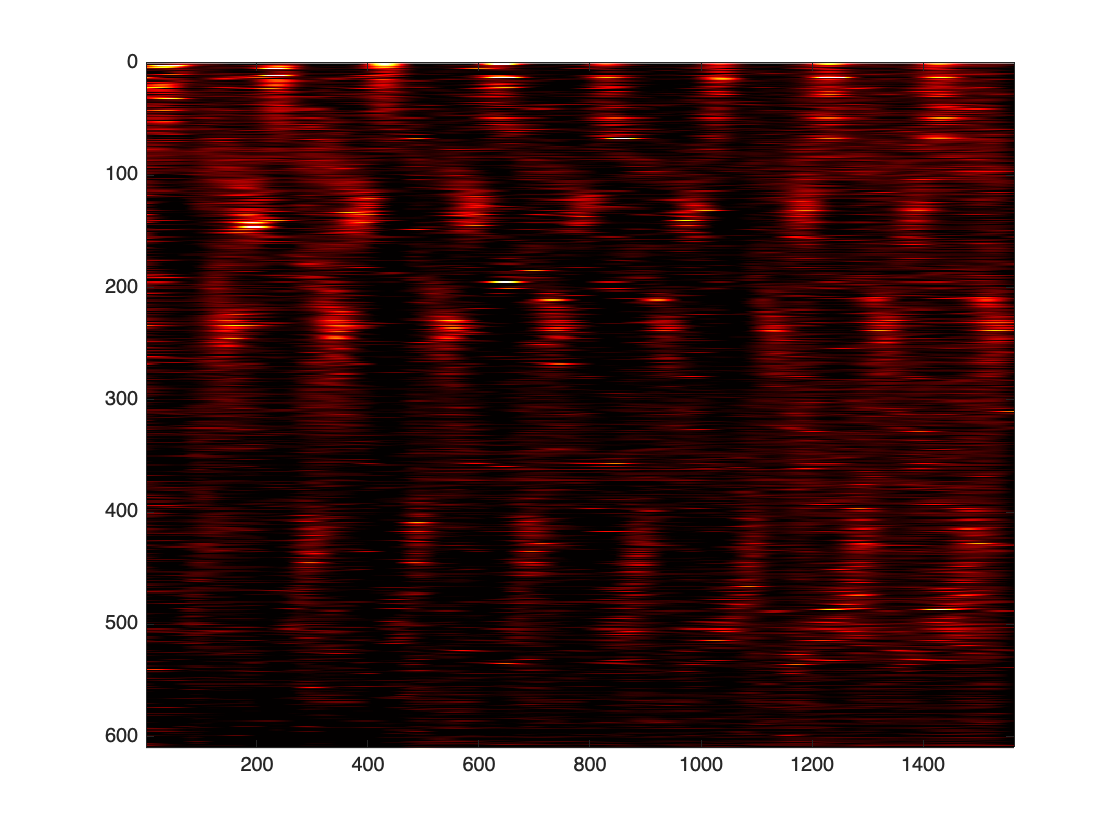

Ftemp=smoothdata(resamp_interpolatedActivity,2,"gaussian",100);
% Ftemp=smoothdata(Ftemp,1,"gaussian",10);
imagesc(Ftemp(isort1,:))
colormap ("hot")
hold on
% plot (-cumulativeDistance/10)
% plot(-interpolatedActivity(124, :)*100-10);
% plot(-interpolatedActivity(427, :)*100-110);
hold off
% plot (-binary_signal*20)
% hold off

caxis ([0 10])
ylim([0 NCell]) 

%mean 10% isort1

meantrace=mean(resamp_interpolatedActivity(isort1(1:200),:),1);


figure
plot(interpolatedActivity(1, :));
hold on
plot(Tr1b(1, :));

% % Initialisation de la matrice de corrélation
% correlationMatrix = zeros(NCell);
% 
% % Calcul de la corrélation croisée pour chaque paire de neurones
% parfor i = 1:NCell
%     for j = 1:NCell % Pas besoin de calculer la diagonale ni de dupliquer les paires
%         correlationMatrix(i,j) = max(xcorr(Tr1b(i,WinActive), Tr1b(j,WinActive), 'coeff'));
%         %correlationMatrix(j,i) = correlationMatrix(i,j); % La matrice est symétrique
%     end
% end
% 
% % Trouver les paires de neurones avec une corrélation élevée
% highCorrelationPairs = correlationMatrix > 0.5; % Supposons un seuil de 0.8
% 
% % Visualiser la matrice de corrélation
% figure
% imagesc(correlationMatrix);
% colorbar;
% title('Matrice de corrélation entre les neurones');
% xlabel('Neurone');
% ylabel('Neurone');
% 
% % Si vous voulez trier les neurones basés sur leur corrélation séquentielle
% % Vous pourriez regarder les lignes ou les colonnes avec le plus de corrélations élevées
% [~, sortedIndices] = sort(sum(highCorrelationPairs, 2), 'descend');
% 
% % Utiliser les indices triés pour réorganiser les données originales
% sortedData = Tr1b(sortedIndices, :);
% 
% % Visualiser les données triées
% figure
% imagesc(sortedData);
% colorbar;
% title('Activité neuronale triée');
% xlabel('Temps');
% ylabel('Neurone (trié)');

% caxis ([1 1.5])
% axis off
% axis image
 
% namegraph=strcat(PathSave ,['allcells' , '.png']);
% 
% exportgraphics(gcf,namegraph,'Resolution',300,'BackgroundColor','black')

for ass=1:numel(assembly)
    %figure('visible','off');
    figure
    Ftemp=smoothdata(Tr1b,2,"gaussian",100);
    % test=smoothdata(test,1,"gaussian",10);
    % newF=Ftemp(isort1,:);
    % imagesc(Ftemp(isort1,:))
    imagesc(Ftemp(isort1,:))
    % imagesc(Race(isort1,:))
    colormap ("hot")
    caxis ([0 6])

    for n=cell2mat(assembly(ass))
        y=find (n==isort1);
        % text(0, y, '.', 'FontSize', 20,'Color',colors(ass,:))
        yline(y,'LineWidth',1,'Color',colors(ass,:))
    end
    % namegraph=strcat(['rastermap_run assembly' num2str(ass), '.png']);
    % 
    % exportgraphics(gcf,[namefull namegraph],'Resolution',300,'BackgroundColor','black')
end
% num_cell_assembly=cell2mat(assembly(1));
% text(xPosition, yHauteur, '*', 'FontSize', 14)
return

%overlap with assembly
for n=1:numel (assembly)
        intersection{n}=intersect(isort1(1:440),cell2mat(assembly(n)));
        inter(n)=numel(intersection{n})/numel(cell2mat(assembly(n)));
end
figure
for n=1:numel (assembly)
    
    bar (inter)
    % hold on
    % title(['intersection cluster ortho' num2str(n)])
end
% hold off


mean_active=median(Ftemp(:,WinActive),2);
histogram(mean_active)
title('mean active')
mean_rest=mean(Ftemp(:,WinRest),2);
% histogram(mean_rest)
% title('mean rest')
% iqr_active=iqr(newF(:,2500:4900),2);
% histogram(iqr_active)
% title('iqr_active')
% iqr_rest=iqr(newF(:,2500:4900),2);
% histogram(iqr_rest)
% title('iqr_rest')

% [a idx]=find(mean_active>1)
idx =find(mean_active>1 & mean_rest<1);
newidx=intersect(idx,isort1);
% [a idx]=find(iqr_active<0.05);
% graythresh(mean_rest)
figure
% imagesc(newF(idx,:))
imagesc(Tr1b(newidx,:))
% DF=newF(a,:);
colormap ("hot")
caxis ([1 1.4])
hold on 
plot (-speed,'Color','k','LineWidth',2)
hold off
ylim ([-30 400])
return

% PSTH=Tr1b(:,)

figure
imagesc(Tr1b(isort1,WinActive))
colormap ("hot")
caxis ([0 0.6])

%calculate cross_correlation with start of run
max_lag=200;
start_run_binary=zeros(1,size(Tr1b,2));
start_run_binary(1,start_indices)=1;
Frun=zeros(NCell,size(Tr1b,2));
Frun(:,WinActive)=Tr1b(:,WinActive);
% smoothed_F=smoothdata(Tr1b,2,"gaussian",100);


for n = 1:NCell
    [cross_corr, lags] = xcorr(start_run_binary, Frun(n,:), max_lag,"coeff");
    [max_corr, idx_max_corr] = max(cross_corr);
    lag_at_max_corr = lags(idx_max_corr);
    max_corr_values(n) = max_corr;
    lags_at_max_corr(n) = lag_at_max_corr;
end



[a b]=sort(lags_at_max_corr);
figure
imagesc(Tr1b(b,:))
colormap ("hot")
caxis ([0 0.6])
hold on
% xline (start_indices,Color='g',LineWidth=1)
% xline (end_indices,Color='w',LineWidth=1)
hold off

% calcul correlation pendant run en fonction distance entre cellules
max_lag = 100;
lag=[-100:-1 1:100];
DF=double(F(iscell(:,1)>0,:));
NCell=size(DF,1);
% Initialize arrays to store results
max_corr_values = zeros(NCell, NCell);
lags_at_max_corr = zeros(NCell, NCell);
distance_ij = zeros(NCell, NCell);
DF=normalize(DF,2,'zscore');
DF=DF(isort1,:);
tic
for i = 1:NCell-1
    for j = i+1:NCell
        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(DF(i, WinActive), DF(j, WinActive), max_lag,"coeff");
             
        
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lag_at_max_corr = lags(idx_max_corr);
        distance_ij(i,j) = sqrt((gcamp_centroid(i,1)-gcamp_centroid(j,1))^2+ (gcamp_centroid(i,2)-gcamp_centroid(j,2))^2);
        distance_ij(i,j)
        % Store results
        max_corr_values(i,j) = max_corr;
        lags_at_max_corr(i,j) = lag_at_max_corr;
    end
    %i
end

figure
scatter(max_corr_values,distance_ij)


highCorrelationPairs = max_corr_values > 0.5; % Supposons un seuil de 0.8

% Si vous voulez trier les neurones basés sur leur corrélation séquentielle
% Vous pourriez regarder les lignes ou les colonnes avec le plus de corrélations élevées
[~, sortedIndices] = sort(sum(max_corr_values, 2), 'descend');
% Utiliser les indices triés pour réorganiser les données originales
sortedData = Tr1b(sortedIndices, :);

% Visualiser les données triées
figure
imagesc(sortedData);
colorbar;
title('Activité neuronale triée');
xlabel('Temps');
ylabel('Neurone (trié)');

% [a b]=sort(lags_at_max_corr);
% figure
% imagesc(Tr1b(b,:))
% colormap ("hot")
% caxis ([0 0.6])
% hold on
% % xline (start_indices,Color='g',LineWidth=1)
% % xline (end_indices,Color='w',LineWidth=1)
% hold off

window=100;
PSTH=[];
for n=8:19%numel(start_indices)
    start=start_indices(n);
    PSTH(:,:,n)=DF(:,start-10:start+400);
end
mean_PSTH=mean(PSTH,3);
figure
imagesc(mean_PSTH(isort1,:))
% imagesc(PSTH(isort1,:,1))
colormap ("hot")
caxis ([0 5])


%find order per run sequence
figure
sm_F=smoothdata(Tr1b,2,"gaussian",10);
imagesc(sm_F(isort1,start_indices(2):end_indices(2)))
colormap ("hot")
caxis ([0 0.6])

DF=double(F(iscell(:,1)>0,:));
NCell=size(DF,1);
DF=normalize(DF,2,'zscore');
DF=DF(isort1,:);


% calcul correlation de toutes les cellules pendant tout le film en fonction distance entre cellules

[correlation_matrix, p_values]= corrcoef(DF');
correlation_matrix(logical(eye(size(correlation_matrix)))) = 0;
correlation_matrix_vector=squareform(correlation_matrix,"tovector");
distances_gcamp_vector = pdist(gcamp_centroid)*size_pixel; % Calcul des distances entre toutes les paires de centres
distances_gcamp_square = squareform(distances_gcamp_vector);
meandistance_gcamp = mean(distances_gcamp_vector);

scatter(distances_gcamp_vector, correlation_matrix_vector, '.'); % Nuage de points
xlabel('Distances gcamp vector');
ylabel('Correlation matrix vector');
title('All neurons ');

%bin=[100 200 300 400 500 600 700 800 900 1000]
edges = 0:100:1000; 
[~,~,bin]  = histcounts(distances_gcamp_vector, edges);
bin = max(1, bin); % Garantir que les valeurs sont au moins 1
bin = min(length(edges), bin); % Garantir que les valeurs sont au maximum la taille des bins
bin_vector = bin(:);
% [~, bin] = histc(distances_gcamp_vector, edges);
% Calculer la moyenne de correlation_matrix_vector pour chaque bin

mean_correlation_per_bin = accumarray(bin_vector, correlation_matrix_vector, [], @mean);
bar(mean_correlation_per_bin)


% calcul correlation de toutes les cellules pendant run en fonction distance entre cellules

[correlation_matrix, p_values]= corrcoef(DF(:, WinActive)');
correlation_matrix(logical(eye(size(correlation_matrix)))) = 0;
correlation_matrix_vector=squareform(correlation_matrix,"tovector");
distances_gcamp_vector = pdist(gcamp_centroid)*size_pixel; % Calcul des distances entre toutes les paires de centres
distances_gcamp_square = squareform(distances_gcamp_vector);
meandistance_gcamp = mean(distances_gcamp_vector);

scatter(distances_gcamp_vector, correlation_matrix_vector, '.'); % Nuage de points
xlabel('Distances gcamp vector');
ylabel('Correlation matrix vector');
title('All neurons during Run');

%bin=[100 200 300 400 500 600 700 800 900 1000]
edges = 0:100:1000; 
[~,~,bin]  = histcounts(distances_gcamp_vector, edges);
bin = max(1, bin); % Garantir que les valeurs sont au moins 1
bin = min(length(edges), bin); % Garantir que les valeurs sont au maximum la taille des bins
bin_vector = bin(:);
% [~, bin] = histc(distances_gcamp_vector, edges);
% Calculer la moyenne de correlation_matrix_vector pour chaque bin

mean_correlation_per_bin = accumarray(bin_vector, correlation_matrix_vector, [], @mean);
bar(mean_correlation_per_bin)
imagesc(correlation_matrix);
colormap ("jet")


% calcul correlation de toutes les cellules pendant rest en fonction distance entre cellules

[correlation_matrix, p_values]= corrcoef(DF(:, WinRest)');
correlation_matrix(logical(eye(size(correlation_matrix)))) = 0;
correlation_matrix_vector=squareform(correlation_matrix,"tovector");
distances_gcamp_vector = pdist(gcamp_centroid)*size_pixel; % Calcul des distances entre toutes les paires de centres
distances_gcamp_square = squareform(distances_gcamp_vector);
meandistance_gcamp = mean(distances_gcamp_vector);

scatter(distances_gcamp_vector, correlation_matrix_vector, '.'); % Nuage de points
xlabel('Distances gcamp vector');
ylabel('Correlation matrix vector');
title('All neurons during Rest');

%bin=[100 200 300 400 500 600 700 800 900 1000]
edges = 0:100:1000; 
[~,~,bin]  = histcounts(distances_gcamp_vector, edges);
bin = max(1, bin); % Garantir que les valeurs sont au moins 1
bin = min(length(edges), bin); % Garantir que les valeurs sont au maximum la taille des bins
bin_vector = bin(:);
% [~, bin] = histc(distances_gcamp_vector, edges);
% Calculer la moyenne de correlation_matrix_vector pour chaque bin

mean_correlation_per_bin = accumarray(bin_vector, correlation_matrix_vector, [], @mean);
bar(mean_correlation_per_bin)

sm_F=smoothdata(DF,2,"gaussian",100);
for n=1:NCell-1
    [corr_mat, p_values]= corrcoef(sm_F(n, WinActive)',sm_F(n+1, WinActive)');
    corr_matrix(n)=corr_mat(2);

end

sm_F=smoothdata(DF,2,"gaussian",100);
% sm_F=smoothdata(DF,1,"gaussian",10);
imagesc(sm_F)
colormap ("hot")
caxis ([0 5])

%
sm_F=smoothdata(DF,2,"gaussian",100);
max_lag = 200;
max_corr_values = zeros(NCell, NCell);
lags_at_max_corr = zeros(NCell, NCell);
distance_ij = zeros(NCell, NCell);

tic
for i = 1:NCell-1
    for j = i+1:NCell
        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(sm_F(i, WinActive), sm_F(j, WinActive), max_lag,"coeff");
                   
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lag_at_max_corr = lags(idx_max_corr);

        % Store results
        max_corr_values(i,j) = max_corr;
        max_corr_values(j,i) = max_corr_values(i,j);

        lags_at_max_corr(i,j) = lag_at_max_corr;
    end
    %i
end
toc

% Paramètres de la fonction
mu = 50; % Moyenne (position du pic)
sigma = 20; % Écart-type (contrôle la largeur du pic)
decay_tau = 300; % Temps caractéristique pour la décroissance (plus grand = décroissance plus lente)
rise_tau = 20;
peak_height = 1; % Hauteur du pic

% Créer un vecteur de valeurs x
x = linspace(-500, 500, 1000); % Par exemple, de -500 à 500 avec 1000 points

% Calculer les valeurs de la fonction
y_gaussian = peak_height * exp(-(x - mu).^2 / (2 * sigma^2)); % Fonction gaussienne pour la montée
%y_gaussian = peak_height * (1 - exp(-x / rise_tau));
y_decay = peak_height * exp(-x / decay_tau); % Fonction exponentielle pour la décroissance

% Combinaison de la montée et de la décroissance
y_combined = y_gaussian .* y_decay;

% Tracer la fonction combinée
plot(x, y_combined);
xlabel('x');
ylabel('Hauteur');

% title('Combinaison d\'une montée rapide et d\'une décroissance lente');

% title('Combinaison d\'une montée rapide et d\'une décroissance lente');

%title('Combinaison d\'une montée rapide et d\'une décroissance lente');


seed_trace=zeros(1,Nz);
for n=start_indices'
    seed_trace(n-20:n+120)=y_combined(480:620);
end
plot(seed_trace)

max_lag = 50;
sm_F=smoothdata(DF,2,"gaussian",100);

for i = 1:NCell

        % Calculate cross-correlation
        [cross_corr, lags] = xcorr(seed_trace(1,WinActive), sm_F(i, WinActive), max_lag,"coeff");
                   
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        lag_at_max_corr = lags(idx_max_corr);

        max_corr_values(i) = max_corr;
        lags_at_max_corr(i) = lag_at_max_corr;

end

[sorted_lags ,idx]=sort(lags_at_max_corr,"descend");
imagesc(sm_F(isort1,:))
colormap ("hot")
caxis ([0 5])
hold on
plot (-seed_trace*100)
plot (-binary_signal*20)
% plot (-cumulativeDistance/10)
% hold off
 
ylim([-100 NCell]) 
hold off
plot(sorted_lags)


[reduction, umap, clusterIdentifiers, extras]=run_umap(transpose(Tr1b),'n_components' ,3);

color_jet=jet((size(reduction,1)));

scatter3 (reduction(WinRest,1),reduction(WinRest,2),reduction(WinRest,3),'.','Color','blue','')
hold on
scatter3 (reduction(WinActive,1),reduction(WinActive,2),reduction(WinActive,3),'.','Color','red')
hold off

%correlation 2 cellules meme couleur vs 2 cellules couleurs différentes
% sm_F=smoothdata(DF,2,"gaussian",100);
pairwise_corr=corr(DF');
pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
mean_pairwise_corr=nanmean(pairwise_corr,'all')

for n=1:6
    pairwise_corr=corr(DF(colorcell==n,:)');
    pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
    mean_pairwise_corr_col(n)=nanmean(pairwise_corr,'all');
end
mean_pairwise_corr_col;

%pick randomly same number of colored cells 1000 times
for n=1:6
    pairwise_corr=[];
    numcell=numel(find (colorcell==n));
    for nshuffle=1:1000
        list_sh=randperm(NCell);
        list_sh=list_sh(1:numcell);
        pairwise_corr=corr(DF(list_sh,:)');
        pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
        mean_pairwise_tmp(nshuffle)=nanmean(pairwise_corr,'all');
    end
    max_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,95);
    min_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,5);
end
mean_pairwise_corr_col
max_pairwise_corr_col_sh
min_pairwise_corr_col_sh


%%cross correlation 2 cellules meme couleur vs 2 cellules couleurs différentes
% sm_F=smoothdata(DF,2,"gaussian",100);
max_lag = 50;
% pairwise_corr=corr(sm_F');
% pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
% mean_pairwise_corr=nanmean(pairwise_corr,'all')

for n=1:6
tic
list_cell=find (colorcell==n);
    for i = list_cell'
        for j = list_cell'
        % Calculate cross-correlation

        [cross_corr, lags] = xcorr(DF(i,:), DF(j,:), max_lag,"coeff");
                   
        % Find maximum correlation and corresponding lag
        [max_corr, idx_max_corr] = max(cross_corr);
        % lag_at_max_corr = lags(idx_max_corr);
        max_corr_values(i,j) = max_corr;
        % max_corr_values(j,i) = max_corr_values(i,j);

        end
    end

    max_corr_values(logical(eye(size(max_corr_values)))) = NaN;
    mean_crosscorr_col(n)=nanmean(max_corr_values,'all');
    toc
end
mean_crosscorr_col


%pick randomly same number of colored cells 1000 times
for n=1:6
    pairwise_corr=[];
    numcell=numel(find (colorcell==n));
    for nshuffle=1:1000
        list_sh=randperm(NCell);
        list_sh=list_sh(1:numcell);
        pairwise_corr=corr(sm_F(list_sh,:)');
        pairwise_corr(logical(eye(size(pairwise_corr)))) = NaN;
        mean_pairwise_tmp(nshuffle)=nanmean(pairwise_corr,'all');
    end
    max_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,99);
    min_pairwise_corr_col_sh(n)=prctile(mean_pairwise_tmp,1);
end
mean_pairwise_corr_col
max_pairwise_corr_col_sh
min_pairwise_corr_col_sh